# `pcolorps` documentation

`pcolorps` is part of Antarctic Mapping Tools for Matlab (Greene et al., 2017). See `List_of_Functions.mlx` for a complete list of functions in AMT. 

Don't have Matlab's Mapping Toolbox? No problem.  `pcolorps` works just like Matlab's `pcolor` or `pcolorm` functions, but plots georeferenced data in Antarctic polar stereographic coordinates (true latitude 71Â°S).

## Syntax

## Description

`pcolorps(lat,lon,Z)` constructs a surface to represent the data grid `Z` corresponding to a georeferenced `lat,lon` grid in South polar stereographic eastings and northings. 

`pcolorps(...,'PropertyName',PropertyValue,...)` specifies any number of surface properties. 

`pcolorps(...,'km')` plots in polar stereographic kilometers instead of the default meters. 

`pcolorps(...,'meridian',meridian)` specifies a meridian longitude in the polar stereographic coordinate conversion. Default meridian is `0`. 

`h = pcolorps(...)` returns a column vector of handles to surface objects.

## Example 1

Plot gridded georeferenced [Bedmap2](http://www.mathworks.com/matlabcentral/fileexchange/42353) data as a pseudocolor plot in cartesian polar stereographic coordinates: 

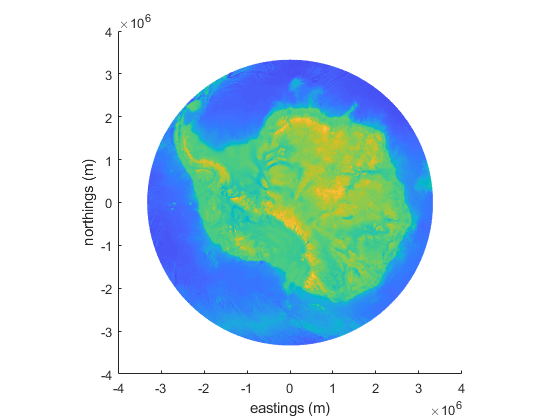

[lat,lon,bed] = bedmap2_data('bed','resolution','5 km'); 

pcolorps(lat,lon,bed)
xlabel('eastings (m)') 
ylabel('northings (m)')

Enhance the appearance of topographic relief with the `shadem` `function.`

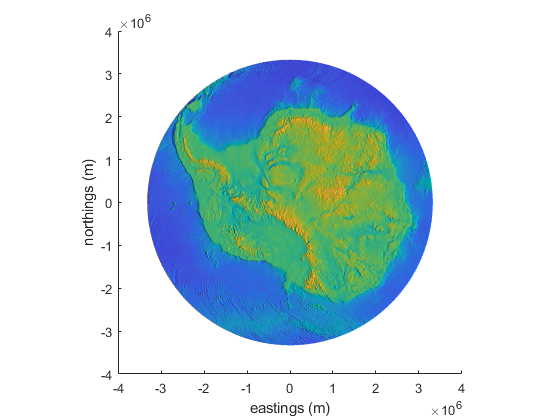

shadem(3)

## Example 2: Rotated coordinates

The example above plotted 5 km resolution data instead of the native 1 km resolution, because `pcolor` and `pcolorps` plots are actually quite slow for large datasets. By plotting 5 km resolution data, we actually cut the amount of datapoints by a factor of 25. If it were me, I would simply use `imagesc` instead of `pcolorps` in the example above, because Bedmap2 is natively gridded in polar stereographic coordinates and `imagesc` is  *much* faster and uses less memory than `pcolor`. 

If you have an irregular grid shape, or if the grid is regular in geo coordinates (and therefore not a perfect grid in polar stereographic), you'll definitely want to use `pcolorps`. Below we create a grid that is regular in latitude and longitude, get some corresponding z values for each grid point, and plot the bathymetry using `pcolorps`. I'm also putting the South Pole at the bottom of the map, and centering everything on the data by setting the meridian to 125 W: 

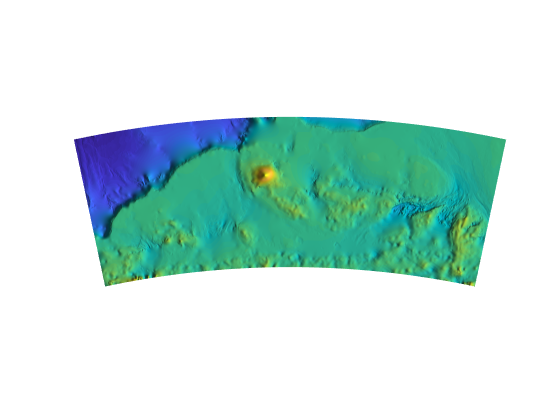

[Lat,Lon] = meshgrid(-75:0.01:-72.5,-137:0.01:-113); 
Z = ibcso_interp(Lat,Lon); 

figure
pcolorps(Lat,Lon,Z,'meridian',-125);
shadem(3)
axis off

## Citing AMT

If this function or any other part of Antarctic Mapping Tools is useful for you, please cite the paper that describes AMT. 

Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function was written by [Chad Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), February 2015, for inclusion in the Antarctic Mapping Tools package. Updated July 2015 to allow plotting in polar stereographic kilometers.